clc; clear all; close all;

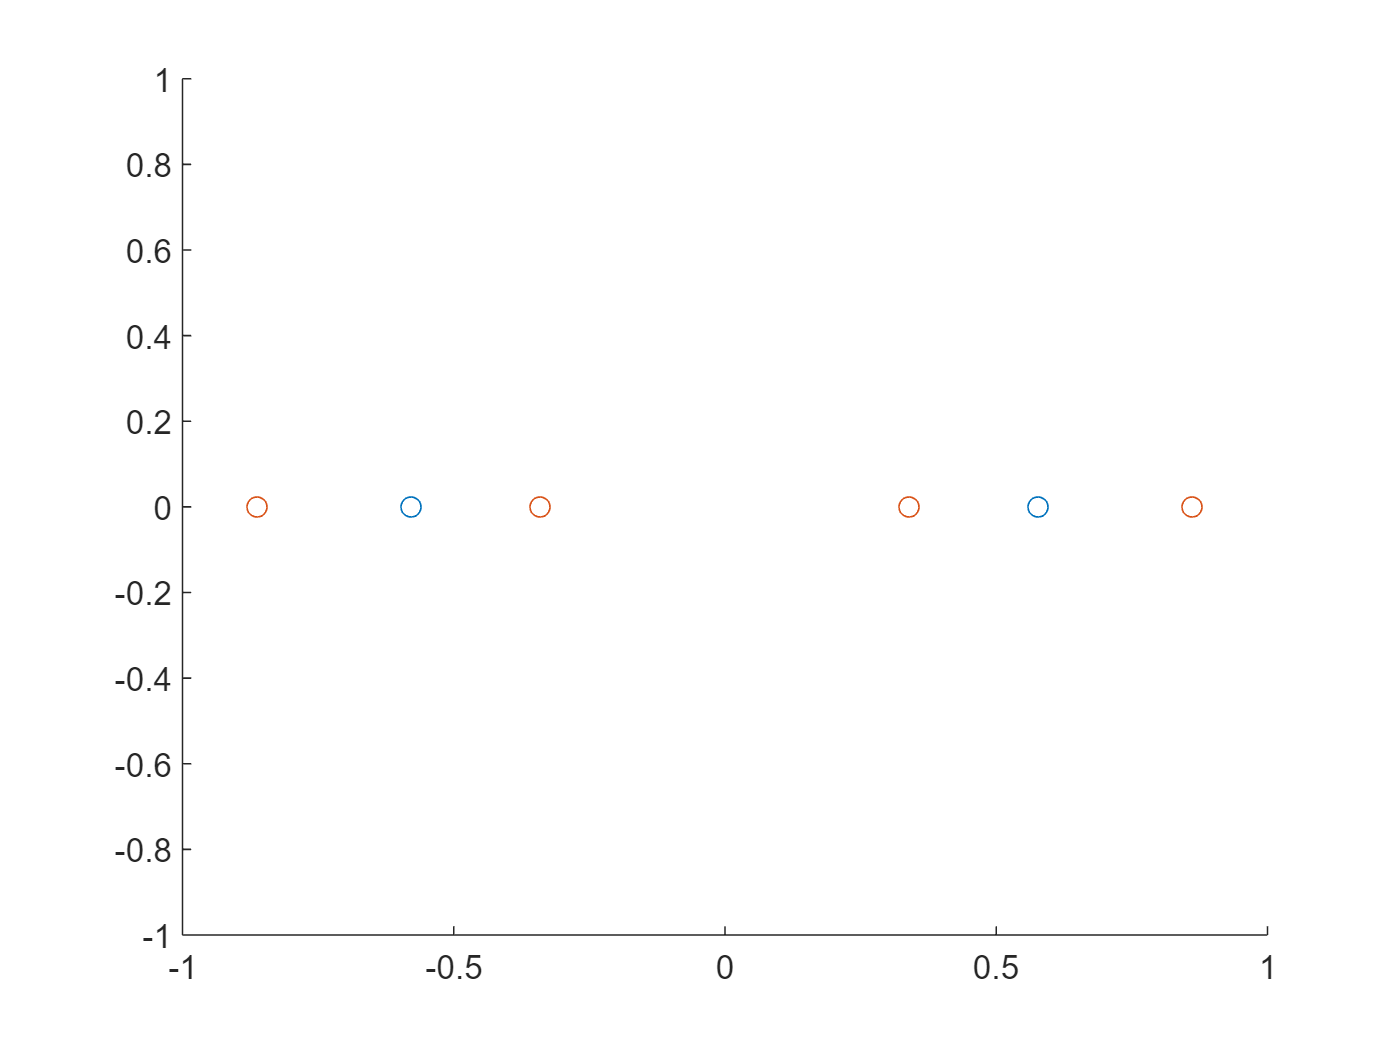

% Function to integrate
f_rs = @(r,s) (r.^2 - 1/2.*r + 2) .* (s.^7 - 2.*s.^4 + 7.*s);

p_r = 2;
p_s = 7;

bounds_r = [-1 1];
bounds_s = [-1 1];

n_r = ceil((p_r + 1) / 2);
n_s = ceil((p_s + 1) / 2);

[xg_r, wg_r] = gaussianPoints(n_r);
[xg_s, wg_s] = gaussianPoints(n_s);

scatter(xg_r, zeros(numel(xg_r), 1)); hold on;
scatter(xg_s, zeros(numel(xg_s), 1));

% Evaluate integral
res = 0;
dxdr = (bounds_r(2) - bounds_r(1)) / 2;
dxds = (bounds_s(2) - bounds_s(1)) / 2;

for r = 1 : numel(xg_r)
    for  s = 1 :  numel(xg_s)
        % xgr = xg(g);
        xgr =   dxdr * xg_r(r) + (bounds_r(1) + bounds_r(2)) / 2;
        xgs =   dxds * xg_s(s) + (bounds_s(1) + bounds_s(2)) / 2;
        res =   res + ...
                dxdr * dxds * ...
                wg_r(r) * wg_s(s) * ...
                f_rs(xgr,xgs);
    end
    % res  = res + dxdr * dxds * wg_r(r) * f_rs(xgr,xgs);
end
res

res = -3.7333

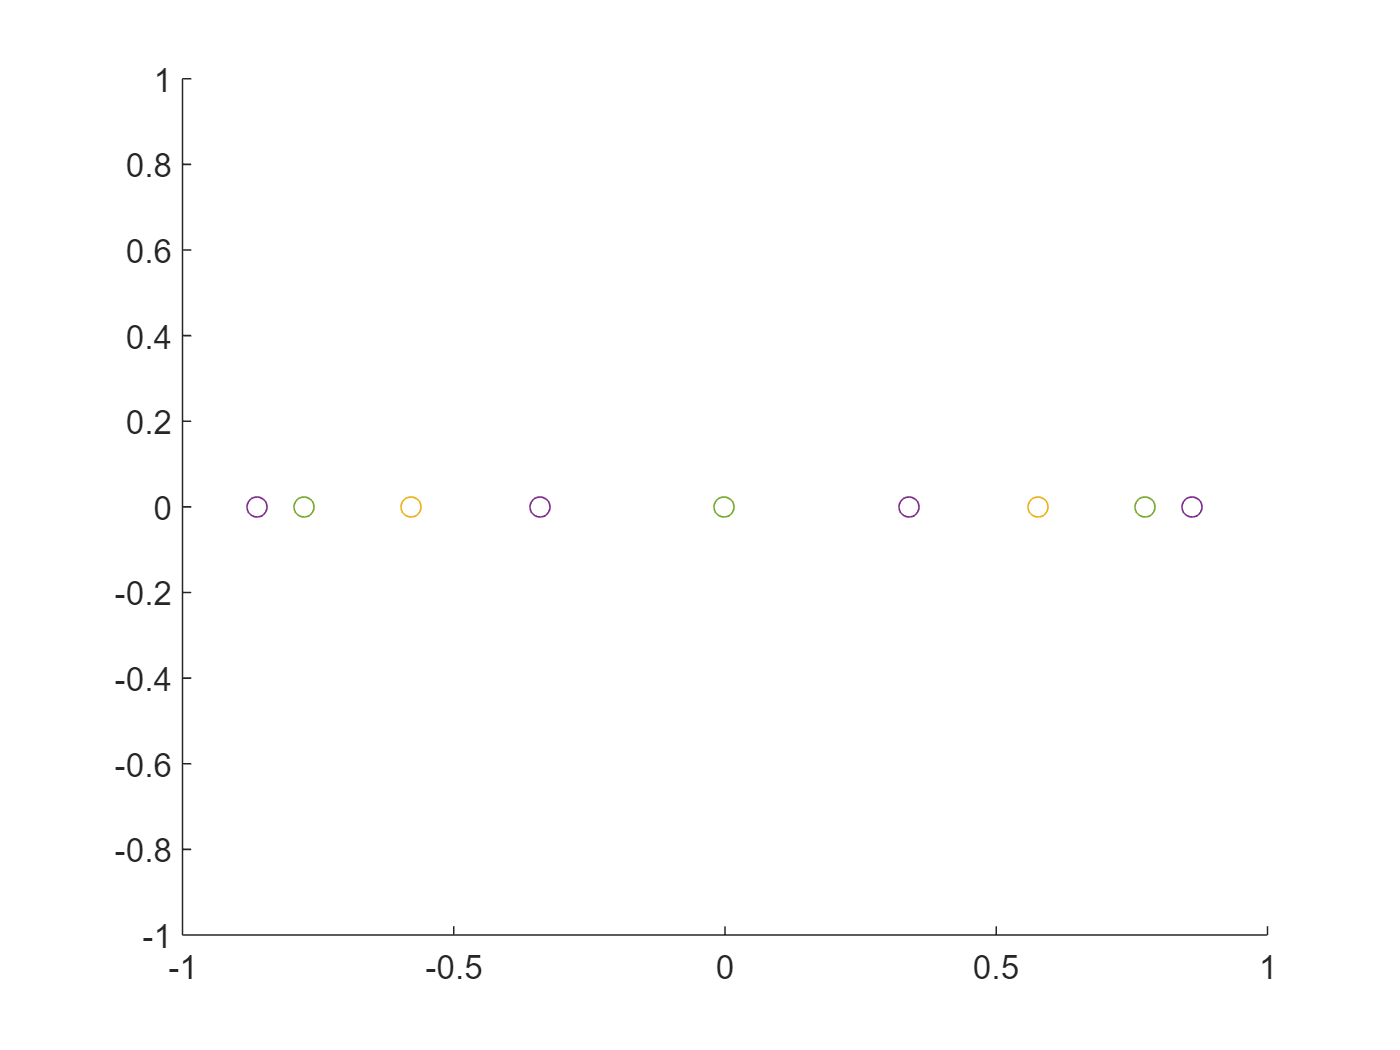

% Function to integrate
f_xyz = @(x,y,z) (x.^2 + 2) .* (y.^7 - 2.*y.^4) .* (7.*z.^5);

p_x = 2;
p_y = 7;
p_z = 5;

bounds_x = [-1 1];
bounds_y = [-1.5 2];
bounds_z = [0.5 1];

n_x = ceil((p_x + 1) / 2);
n_y = ceil((p_y + 1) / 2);
n_z = ceil((p_z + 1) / 2);

[xg_x, wg_x] = gaussianPoints(n_x);
[xg_y, wg_y] = gaussianPoints(n_y);
[xg_z, wg_z] = gaussianPoints(n_z);

scatter(xg_x, zeros(numel(xg_x), 1)); hold on;
scatter(xg_y, zeros(numel(xg_y), 1)); hold on;
scatter(xg_z, zeros(numel(xg_z), 1));

% Evaluate integral
res = 0;
dxdx = (bounds_x(2) - bounds_x(1)) / 2;
dxdy = (bounds_y(2) - bounds_y(1)) / 2;
dxdz = (bounds_z(2) - bounds_z(1)) / 2;

for x = 1 : numel(xg_x)
    for  y = 1 :  numel(xg_y)
        for  z = 1 :  numel(xg_z)
            % xgr = xg(g);
            xgx =   dxdx * xg_x(x) + (bounds_x(1) + bounds_x(2)) / 2;
            xgy =   dxdy * xg_y(y) + (bounds_y(1) + bounds_y(2)) / 2;
            xgz =   dxdz * xg_z(z) + (bounds_z(1) + bounds_z(2)) / 2;
            res =   res + ...
                    dxdx * dxdy * dxdz * ...
                    wg_x(x) * wg_y(y) * wg_z(z) * ...
                    f_xyz(xgx,xgy,xgz);
        end
    end
    % res  = res + dxdr * dxds * wg_r(r) * f_rs(xgr,xgs);
end
res

res = 69.4515

function P = legendrePoly(x, n)
    %{
        Evaluate and return Legendre polynomial
        INPUT
          x (array)   Evaluation points
          n (scalar)  Degree of polynomial
        OUTPUT
          P (array)   Polynomial values for input x
    %}    
    if n == 0
        P = ones(size(x));
    elseif n == 1
        P = x;
    else
        % recursive formultation
        P = ((2 * n - 1) * x .* legendrePoly(x, n - 1) - (n - 1) * legendrePoly(x, n - 2)) ./ n;
    end
end



function dP = legendrePolyDerivative(x, n)
    %{
        Evaluate and return derivative of Legendre polynomial
        INPUT
          x (array)   Evaluation points
          n (scalar)  Degree of polynomial derivative
        OUTPUT
          dP (array)  Derivatives for input x
    %}

    % recursive formultation
    dP = n / (x ^ 2 - 1) * (x * legendrePoly(x, n) - legendrePoly(x, n - 1));
end



function [xg, wg] = gaussianPoints(n)
    %{
        Compute gaussian points and weights for given integration order
        INPUT
          n (scalar, array)   Scalar or array of scalars for integration order in dimensions
        OUTPUT
          xg (array)          Array of gaussian points
          wg (array)          Weights for gaussian points xg
    %}

    % Newton-Rhapson method for finding roots of polynomial
    roots = zeros(floor(n / 2), 1);
    for i = 1 : floor(n / 2)
        % initial guess
        x0 = cos(pi * (i - 1 / 4) / (n + 1 / 2));

        % Newton's Method
        fhp     = @(x) legendrePoly(x, n);
        fhdp    = @(x) legendrePolyDerivative(x, n);

        x       = findRoot(fhp, fhdp, x0, 1e-9);
        roots(i)= x;
    end

    if mod(n, 2) == 0   % if order is even 
        xg = sort([-1 * roots; roots]);
    else
        xg = sort([-1 * roots; 0; roots]);
    end
    
    % Calculate weights
    wg = zeros(size(xg));
    for i = 1 : numel(xg)
        xi = xg(i);
        wg(i) = 2 / ((1 - xi ^ 2) * legendrePolyDerivative(xi, n) ^ 2);
    end
end



function xn = findRoot(f, df, x0, tolerance)
    %{
        Find roots of function f using Newton's method starting at x0
        INPUT
          f (function handle)     Function handle to function whose roots are to be determined
          df (function handle)    Derivative of function f
          x0  (scalar)            Start point for algorithm
          tolerance (scalar)      Tolerance for convergence check
        OUTPUT
          xn (scalar)             Root of f after convergence of algorithm
    %}

    xn = x0;
    nIter = 0;
    err = 1;
    while err > tolerance && nIter < 100 
        x = xn - f(xn) ./ df(xn);
        err = abs(x - xn);
        xn = x;
        nIter = nIter + 1;
    end
end
